% function [] = HW1P3(q,s,h,theta,T)
clc
clear
%test case
T=[1 0 0 2;0 1 0 0;0 0 1 0;0 0 0 1]

T =      1     0     0     2
     0     1     0     0
     0     0     1     0
     0     0     0     1


q=[0, 2, 0]

q =      0     2     0


s_hat=[0,0,1]

s_hat =      0     0     1


h=2

h = 2

theta_a=pi

theta_a = 3.1416

theta=[theta_a/4 theta_a/2 3*theta_a/4 theta_a]

theta =     0.7854    1.5708    2.3562    3.1416


%set variables
% T=T_sa %(set to your own T)
R=T(1:3,1:3)

R =      1     0     0
     0     1     0
     0     0     1


p=[T(1:3,4)]

p =      2
     0
     0


zero=[0 0 0;0 0 0;0 0 0]

zero =      0     0     0
     0     0     0
     0     0     0


I=[1 0 0;0 1 0;0 0 1]

I =      1     0     0
     0     1     0
     0     0     1


% from q, s, and h to S_theta and exp(S_theta)
S=[s_hat.';(-cross(s_hat,q)+h*s_hat).']

S =      0
     0
     1
     2
     0
     2


omega=S(1:3);
v=S(4:6);
omega_box=[0,-omega(3),omega(2);
       omega(3),0,-omega(1);
       -omega(2),omega(1),0];
S_box=[omega_box v;0 0 0 0]

S_box =      0    -1     0     2
     1     0     0     0
     0     0     0     2
     0     0     0     0


exp_S_theta1=expm(S_box*theta(1));
exp_S_theta2=expm(S_box*theta(2));
exp_S_theta3=expm(S_box*theta(3));
exp_S_theta4=expm(S_box*theta(4));
%find T_1
T11=exp_S_theta1*T

T11 =     0.7071   -0.7071         0    2.8284
    0.7071    0.7071         0    2.0000
         0         0    1.0000    1.5708
         0         0         0    1.0000


T12=exp_S_theta2*T

T12 =     0.0000   -1.0000         0    2.0000
    1.0000    0.0000         0    4.0000
         0         0    1.0000    3.1416
         0         0         0    1.0000


T13=exp_S_theta3*T

T13 =    -0.7071   -0.7071         0    0.0000
    0.7071   -0.7071         0    4.8284
         0         0    1.0000    4.7124
         0         0         0    1.0000


Tfinal=exp_S_theta4*T

Tfinal =    -1.0000   -0.0000         0   -2.0000
    0.0000   -1.0000         0    4.0000
         0         0    1.0000    6.2832
         0         0         0    1.0000


%plot
R1=T11(1:3,1:3)

R1 =     0.7071   -0.7071         0
    0.7071    0.7071         0
         0         0    1.0000


rotations=rotm2quat(R1)

rotations =     0.9239         0         0    0.3827


translations=T11(1:3,4).'

translations =     2.8284    2.0000    1.5708


ax=plotTransforms(translations,rotations,FrameAxisLabels="on",AxisLabels="on")

ax =   Axes with properties:

             XLim: [2 3.5355]
             YLim: [2 2.8000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


hold on
R2=T12(1:3,1:3)

R2 =     0.0000   -1.0000         0
    1.0000    0.0000         0
         0         0    1.0000


rotations=rotm2quat(R2)

rotations =     0.7071         0         0    0.7071


translations=T12(1:3,4).'

translations =     2.0000    4.0000    3.1416


plotTransforms(translations,rotations,FrameAxisLabels="on",AxisLabels="on")
R3=T13(1:3,1:3)

R3 =    -0.7071   -0.7071         0
    0.7071   -0.7071         0
         0         0    1.0000


rotations=rotm2quat(R3)

rotations =     0.3827         0         0    0.9239


translations=T13(1:3,4).'

translations =     0.0000    4.8284    4.7124


plotTransforms(translations,rotations,FrameAxisLabels="on",AxisLabels="on")
R4=Tfinal(1:3,1:3)

R4 =    -1.0000   -0.0000         0
    0.0000   -1.0000         0
         0         0    1.0000


rotations=rotm2quat(R4)

rotations =     0.0000         0         0    1.0000


translations=Tfinal(1:3,4).'

translations =    -2.0000    4.0000    6.2832


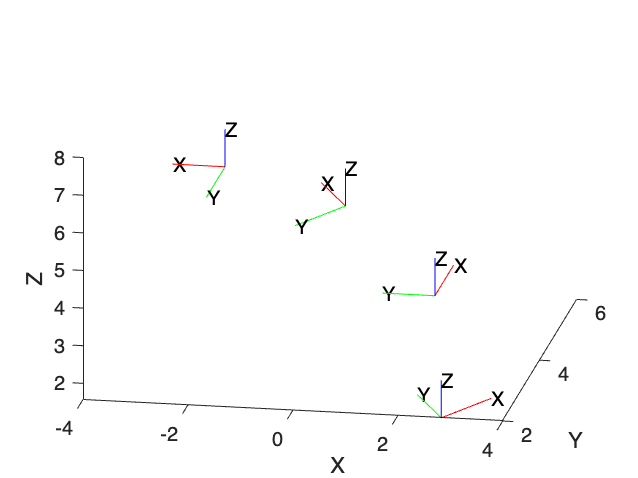

plotTransforms(translations,rotations,FrameAxisLabels="on",AxisLabels="on")
hold off

view([10.04 27.03])

figure
%find adjoint to reverse S to find S1
p_box=[0,-p(3),p(2);
       p(3),0,-p(1);
       -p(2),p(1),0]

p_box =      0     0     0
     0     0    -2
     0     2     0


AdT=[R zero;(p_box*R) R]

AdT =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0    -2     0     1     0
     0     2     0     0     0     1


input_twist=S

input_twist =      0
     0
     1
     2
     0
     2


S1=AdT*input_twist

S1 =      0
     0
     1
     2
    -2
     2


theta_1= acos(.5*(trace(R4)-1))

theta_1 = 3.1416

v1=S1(1:3)

v1 =      0
     0
     1


v1_box=[0,-v(3),v(2);
       v(3),0,-v(1);
       -v(2),v(1),0];
if omega == 0
    theta_dot=norm(v);
else
    theta_dot=norm(omega);
end
if norm(omega) == 1
    h=0;
elseif omega == 0 & norm(v) == 1
    h='infinity';
else
    h=omega\v;
end
s_hat=omega/theta_dot

s_hat =      0
     0
     1


q1=(-omega)\v1_box

q1 =      0    -2     0


quiver3(q1(1),q1(2),q1(3),s_hat(1),s_hat(2),s_hat(3))